cd('/Volumes/PcSSDA/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

cd('/Volumes/PcSSDA/20220206_112_8_AChMut_SW_001')
ExperimentName='20220206_112_8_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7; % What's the acquisition number of the first offical recording
number_of_acq = 12; % How many chunks of recordings are there?
Dark_hours=[7 8 9 10 11 12 13 14 15 16 17 18]

Dark_hours =      7     8     9    10    11    12    13    14    15    16    17    18


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 2 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

cd('/Volumes/PcSSDA/20220425_109_AChmut_SW_001')
ExperimentName='20220425_109_AChmut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=11; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='109 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

cd('/Volumes/PcSSDA/20220207_109_AChMut_SW_001')
ExperimentName='20220207_109_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 10; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='109 AChmut 2 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


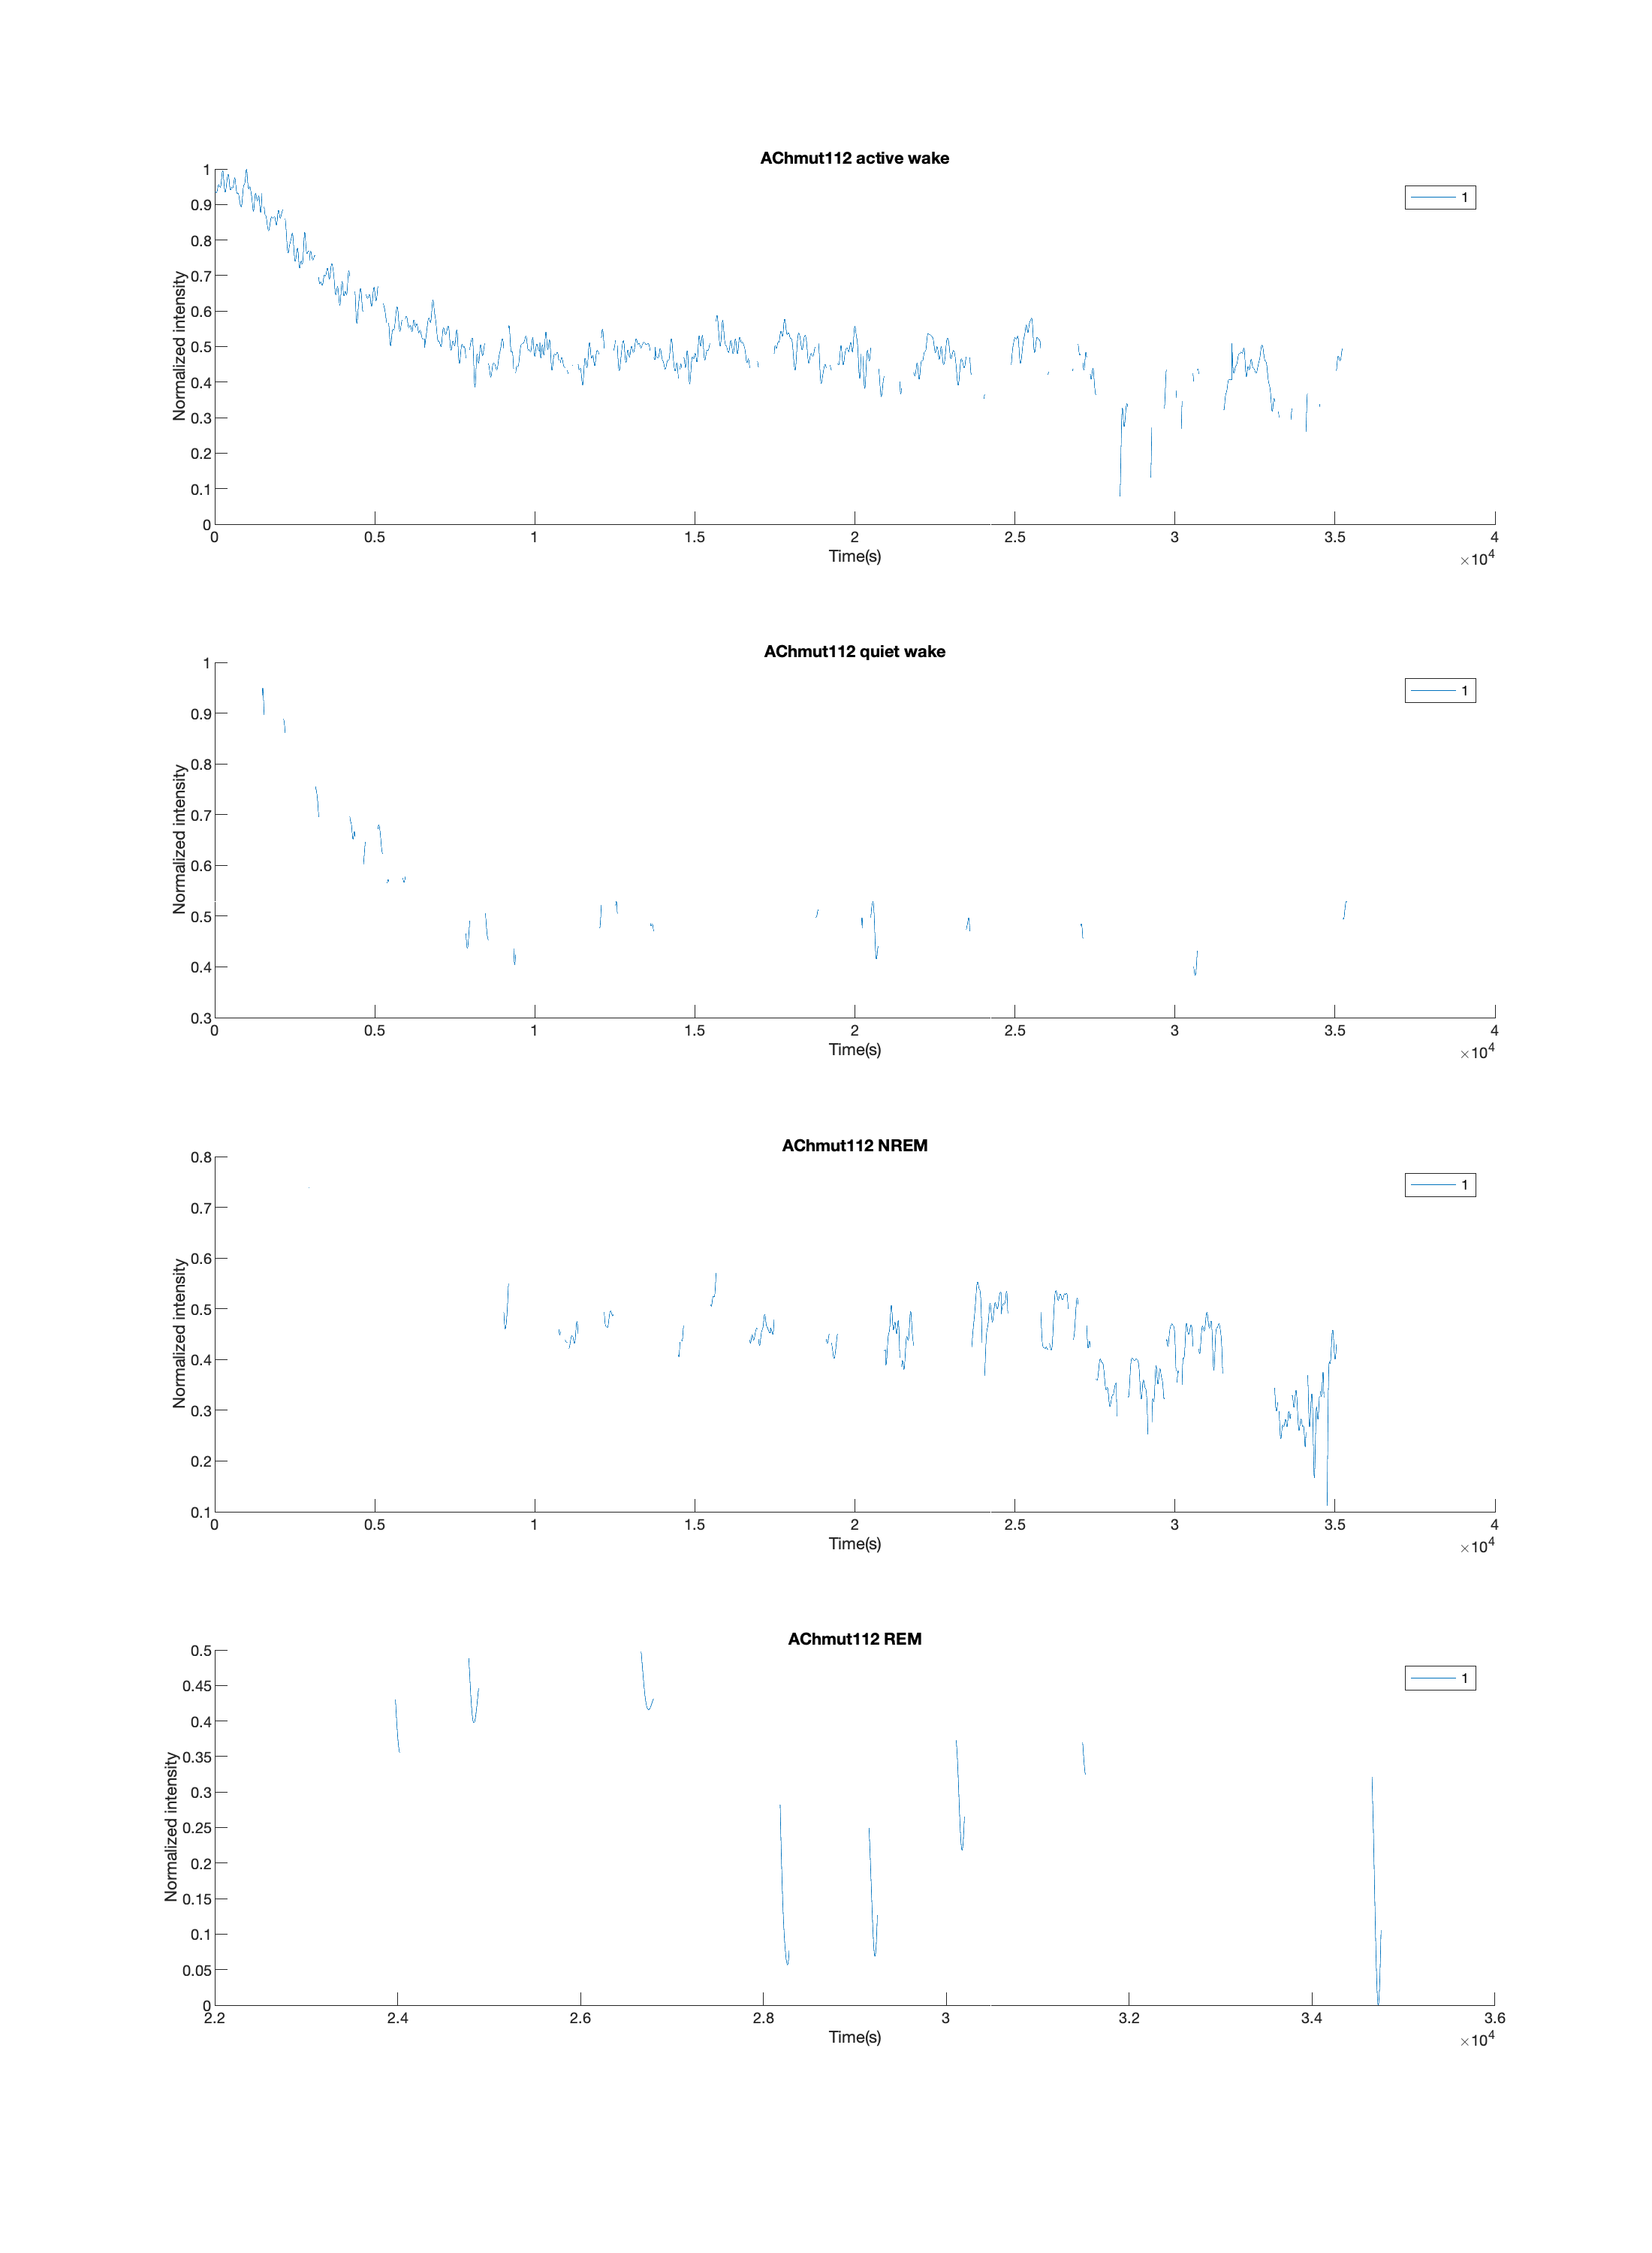

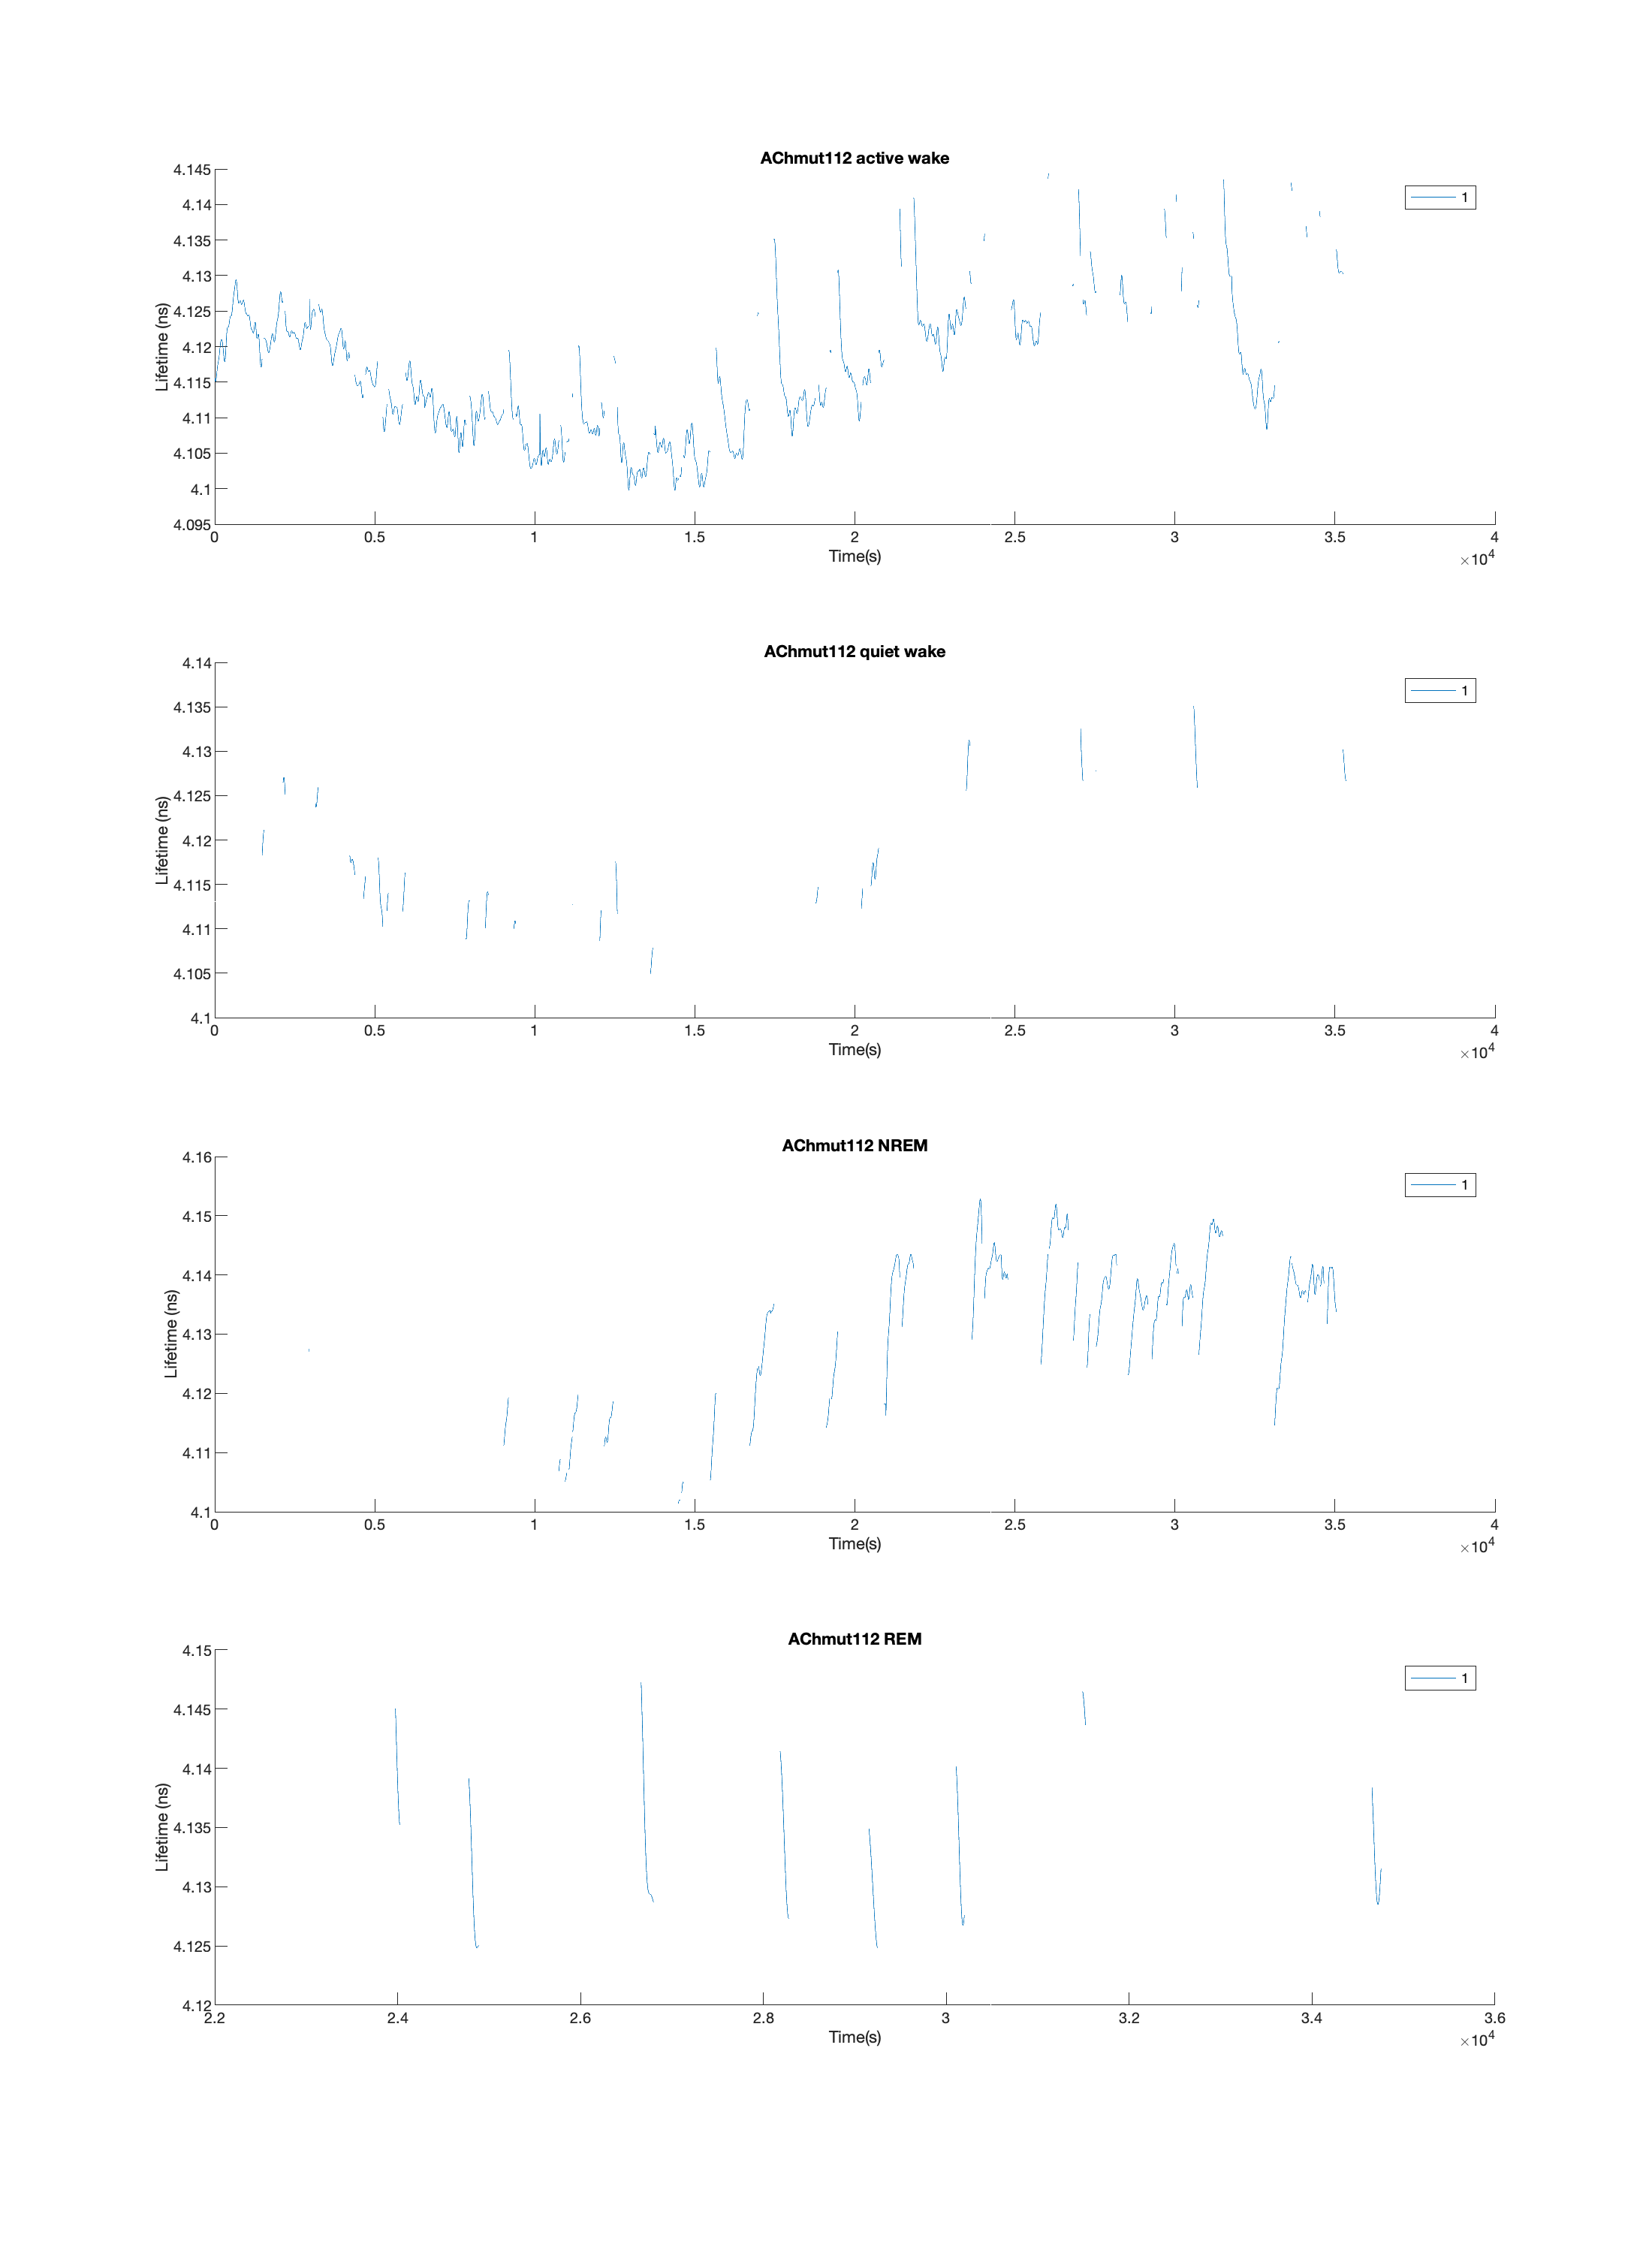

load('FLP_analysis.mat');

% This is the 1st format, a 900 long number serie, called states_#h.
states_all=[];
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    eval(['states_all=[states_all; states_',num2str(Dark_hours(i)),'h];']);
end

states_all(find(states_all==2))=0;
states_all(find(states_all==3))=1;
states_all(find(states_all==4))=1;
prior_wake=zeros(900,1)+1;

flagsWakeREM = [states_all;states_all;states_all;states_all;states_all;states_all;states_all;states_all]; % Convert wake & REM to '1', and NREM to '0'

length(tau_empTrunc_all_darkonly)

ans =        41436


length(intensity_all_darkonly)

ans =        41436


tau_empTrunc_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
time_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
states_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);

for i=1:ceil(length(intensity_all_darkonly)/4)
    tau=tau_empTrunc_all_darkonly((i-1)*4+1:(i-1)*4+4);
    intensity=intensity_all_darkonly((i-1)*4+1:(i-1)*4+4);
    tau_empTrunc_pooled(i)=sum(tau.*intensity)/sum(intensity);
    time_pooled(i)=time_z_all_darkonly((i-1)*4+1);
    states_pooled(i)=states_for_time_all_dark((i-1)*4+1);
end

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

cd('/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature')
save('states_and_tau.mat','time_pooled','tau_empTrunc_pooled','states_pooled')


% Define initial input
initial_temperature = 35.5; % negative value produces an estimated initial temperature
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = 3;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = -1.4;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = 34.26;   % Lower asymptote value (in C)
p.upperAsymptote =  36.28;  % Upper Asymptote value (in C)
p.wakeTimeConstant = 0.21;  % Time constant of wake and REM states
p.nremTimeConstant = 0.11;  % Time constant of NREM sleep
p.scalePWP = 1.01;          % The multiplier of PWP values
p.circadianAmplitude = 0.19;% The multiplier of the circadian values
p.circadianPhase = -0.71;   % Phase shift of circadian process (in hours)

% Define initial input
initial_temperature = -1; % negative value produces an estimated initial temperature
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = 5;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = 1.5;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = 35;   % Lower asymptote value (in C)
p.upperAsymptote =  36.5;  % Upper Asymptote value (in C)
p.wakeTimeConstant = 0.4;  % Time constant of wake and REM states
p.nremTimeConstant = 0.01;  % Time constant of NREM sleep
p.scalePWP = 1.8;          % The multiplier of PWP values
p.circadianAmplitude = 0.19;% The multiplier of the circadian values
p.circadianPhase = -1;   % Phase shift of circadian process (in hours)

[simulatedT,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220206_112_8_AChMut_SW_001FLIM001.mat'
     folder: '/Volumes/PcSSDA/20220206_112_8_AChMut_SW_001'
       date: '06-Feb-2022 18:05:20'
      bytes: 2877
      isdir: 0
    datenum: 7.3856e+05


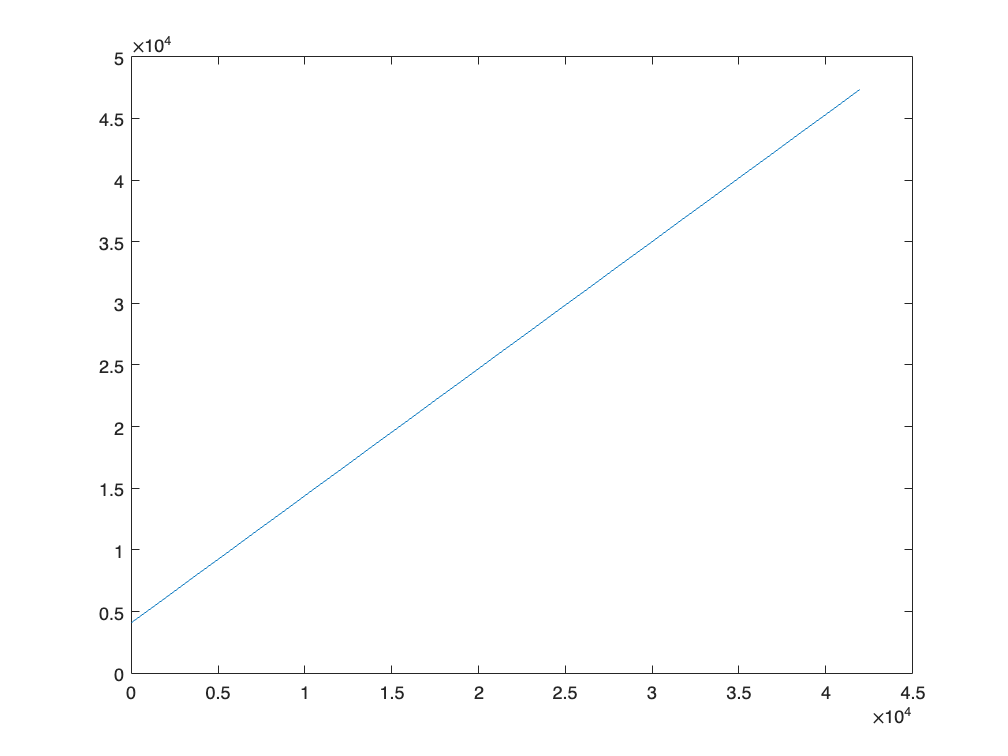

starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day,18,0,0);

time_z_all=[];
tau_empTrunc_all=[];
intensity_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220510.mat'];
    load(filename);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time);
    time_z_all=[time_z_all; time_z];
    tau_empTrunc_all=[tau_empTrunc_all; tau_empTrunc];
    intensity_all=[intensity_all; photoncount];
end

time_z_all_norm=time_z_all-time_z_all(1);

figure
plot(time_z_all)

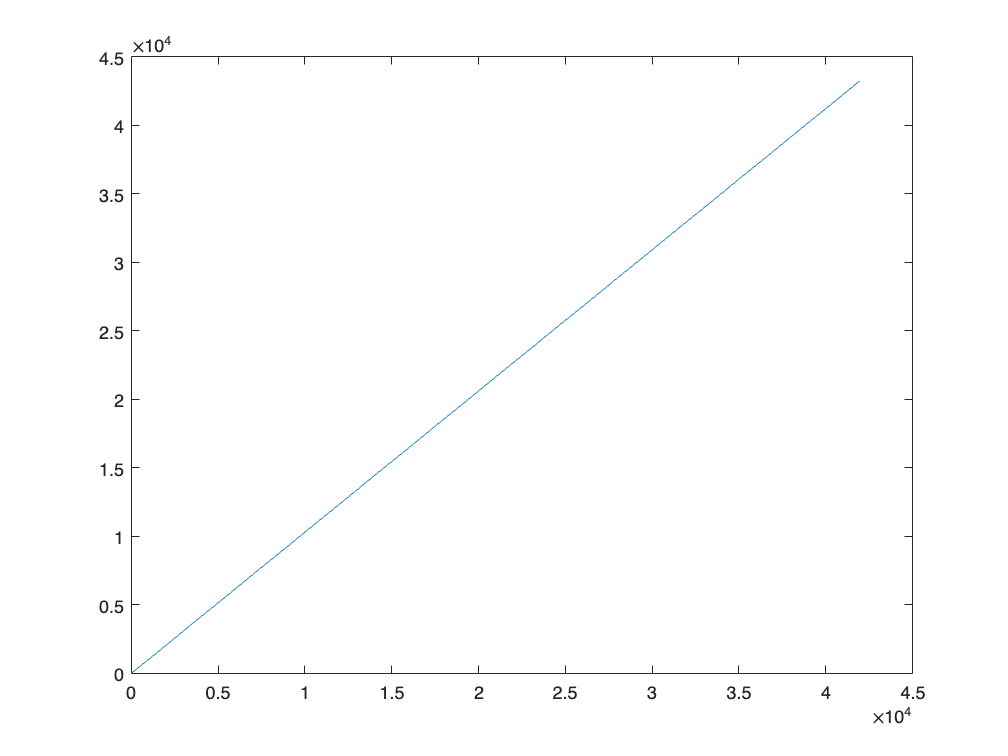


figure
plot(time_z_all_norm)

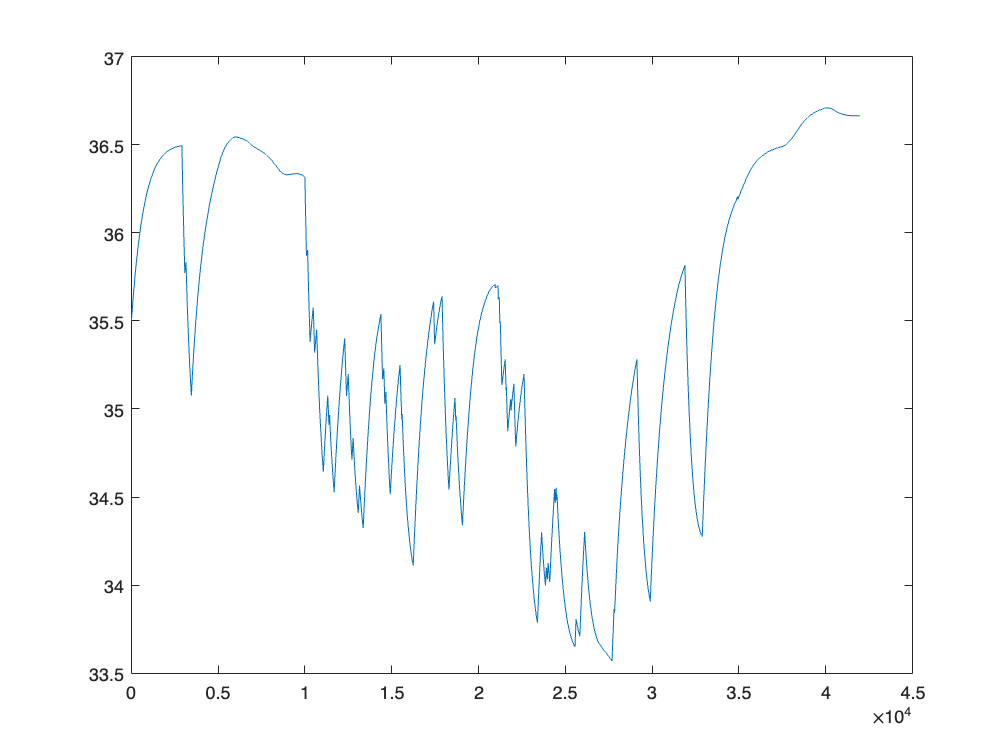

T_in_seconds=[];
asymptots_up=[];
asymptots_low=[];
states_in_seconds=[];
% simulatedT(1:900)=[];

for j=1:size(states_all,1)
    T_in_seconds((4*j-3):4*j)=simulatedT(j);
    states_in_seconds((4*j-3):4*j)=states_all(j);

end

T_for_time=[];
states_for_time=[];
T_for_time(1)=T_in_seconds(1);
states_for_time(1)=states_in_seconds(1);


for j=2:length(time_z_all_norm)
    if ceil(time_z_all_norm(j))<length(T_in_seconds)
        T_for_time(j)=T_in_seconds(ceil(time_z_all_norm(j)));
        states_for_time(j)=states_in_seconds(ceil(time_z_all_norm(j)));
    else
        T_for_time(j)=T_in_seconds(end);
        states_for_time(j)=states_in_seconds(end);
    end
end

figure
plot(T_for_time)


correlation = corr(T_for_time',tau_empTrunc_all_dark)

correlation = -0.7626

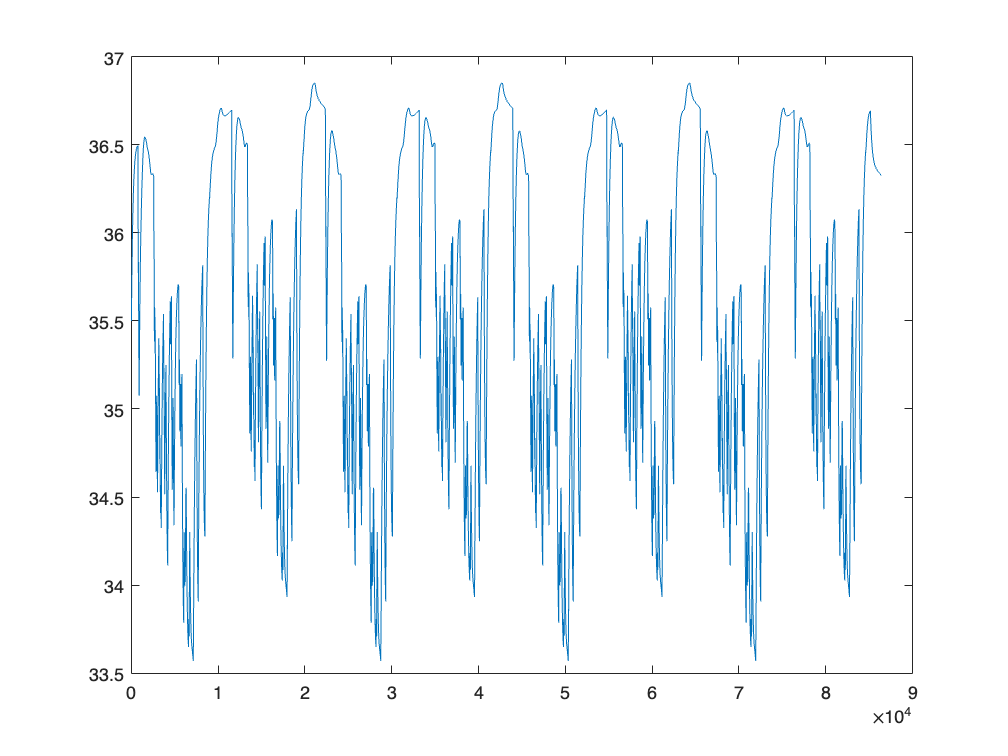

T_time=1:4:size(states_all,1)*4;

figure
plot(simulatedT)

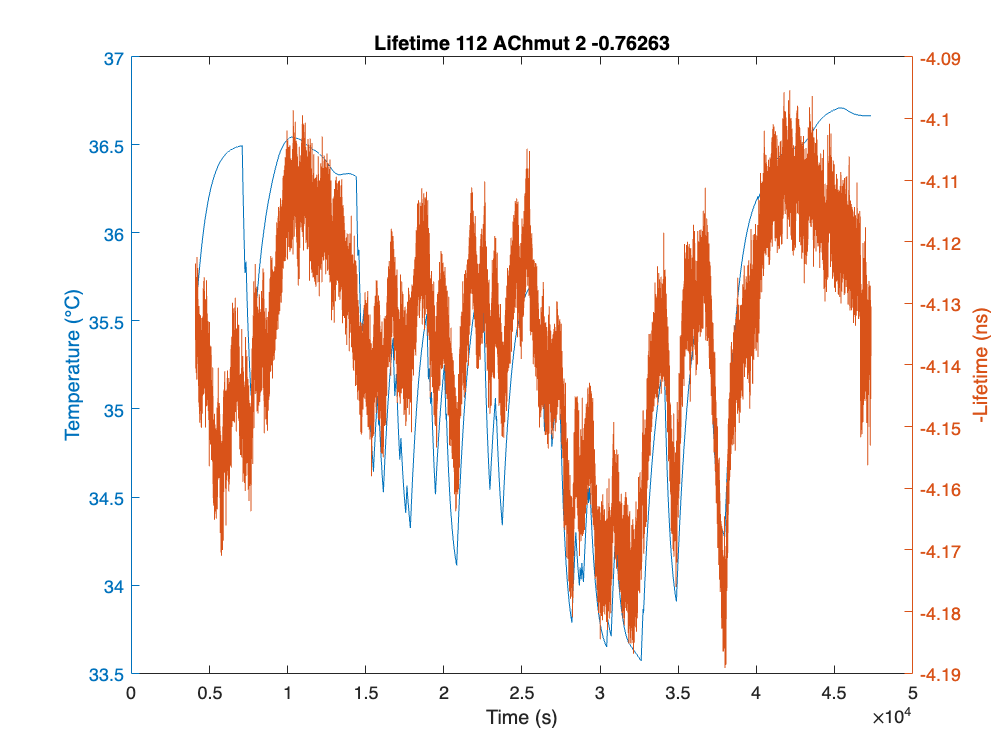



figure
yyaxis left
plot(time_z_all,T_for_time)
ylabel('Temperature (℃)')
yyaxis right
plot(time_z_all,-tau_empTrunc_all_dark)
ylabel('-Lifetime (ns)')
xlabel('Time (s)')
title(['Lifetime ',animal,num2str(correlation)])

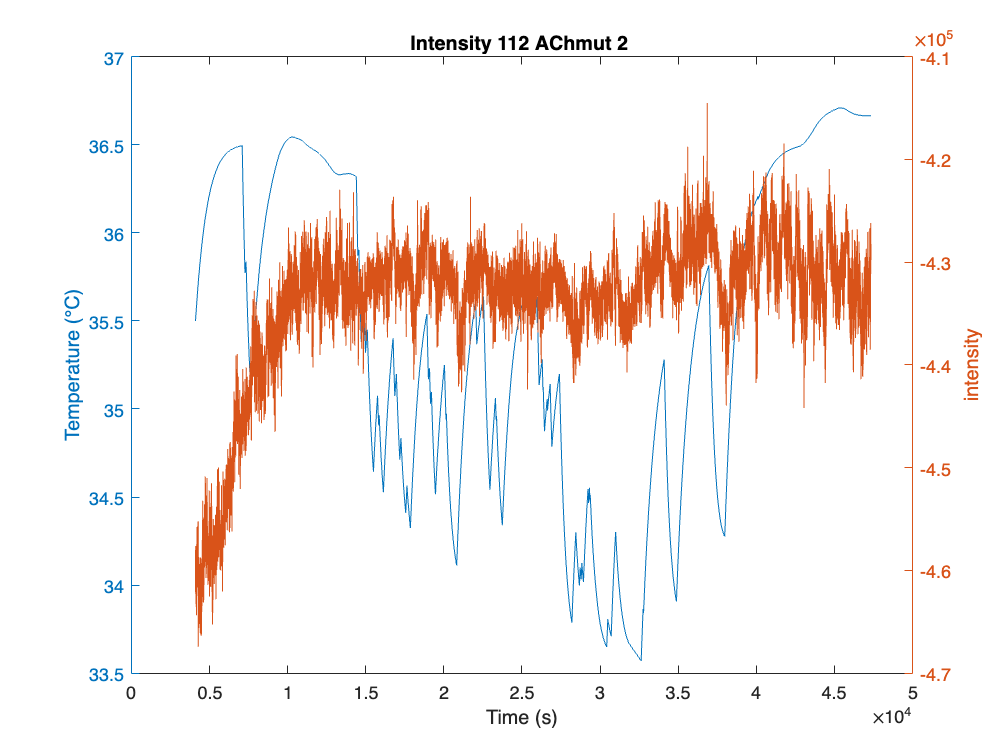




figure
yyaxis left
plot(time_z_all,T_for_time)
ylabel('Temperature (℃)')
yyaxis right
plot(time_z_all,-intensity_all_dark)
ylabel('intensity')
xlabel('Time (s)')
title(['Intensity ',animal])

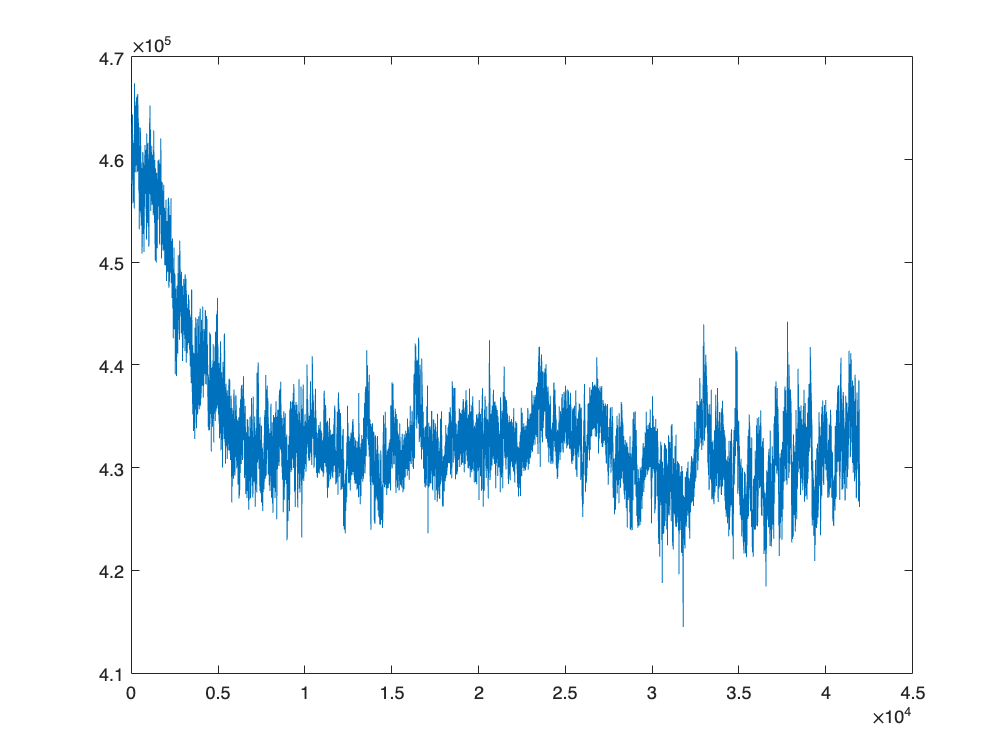


figure
plot(intensity_all_dark)

light_range=find(time_z_all>=12*3600);
range_end=max([min(light_range) length(time_z_all)])

range_end = 45437

range_start=8000;

tau_modified=tau_empTrunc_all_dark(range_start:range_end);
T_modified=T_for_time(range_start:range_end);
time_modified=time_z_all(range_start:range_end);
intensity_modified=intensity_all_dark(range_start:range_end);
states_modified=states_for_time(range_start:range_end);

correlation2 = corr(T_modified',tau_modified)

correlation2 = -0.8247

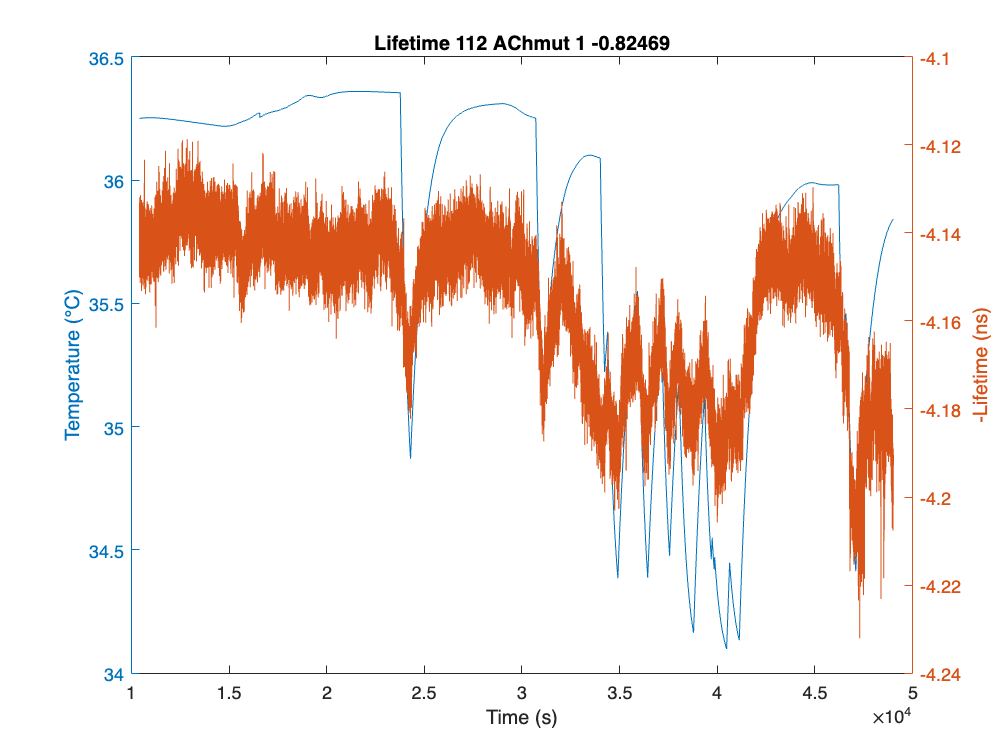


figure
yyaxis left
plot(time_modified,T_modified)
ylabel('Temperature (℃)')
yyaxis right
plot(time_modified,-tau_modified)
ylabel('-Lifetime (ns)')
xlabel('Time (s)')
title(['Lifetime ',animal,num2str(correlation2)])

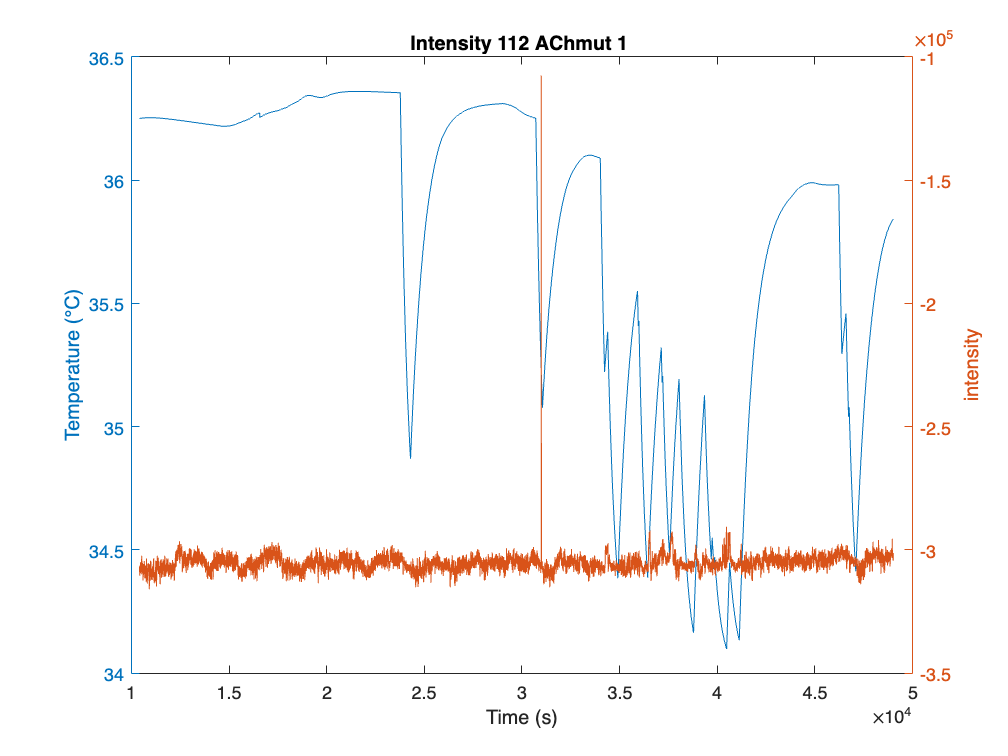


figure
yyaxis left
plot(time_modified,T_modified)
ylabel('Temperature (℃)')
yyaxis right
plot(time_modified,-intensity_modified)
ylabel('intensity')
xlabel('Time (s)')
title(['Intensity ',animal])

tau_plot=NaN(length(tau_modified),9);
colors=["blue","red","yellow","green","magenta","cyan","blue","red","yellow"];
figure
yyaxis right

for i=1:8
    this_range=find(time_modified >= i*5000 & time_modified < (i*5000+5000));
    tau_plot(this_range,i)=tau_modified(this_range);
    plot(time_modified(this_range),-tau_modified(this_range),'Color',colors(i))
    hold on
end

legend('1','2','3','4','5','6','7','8')

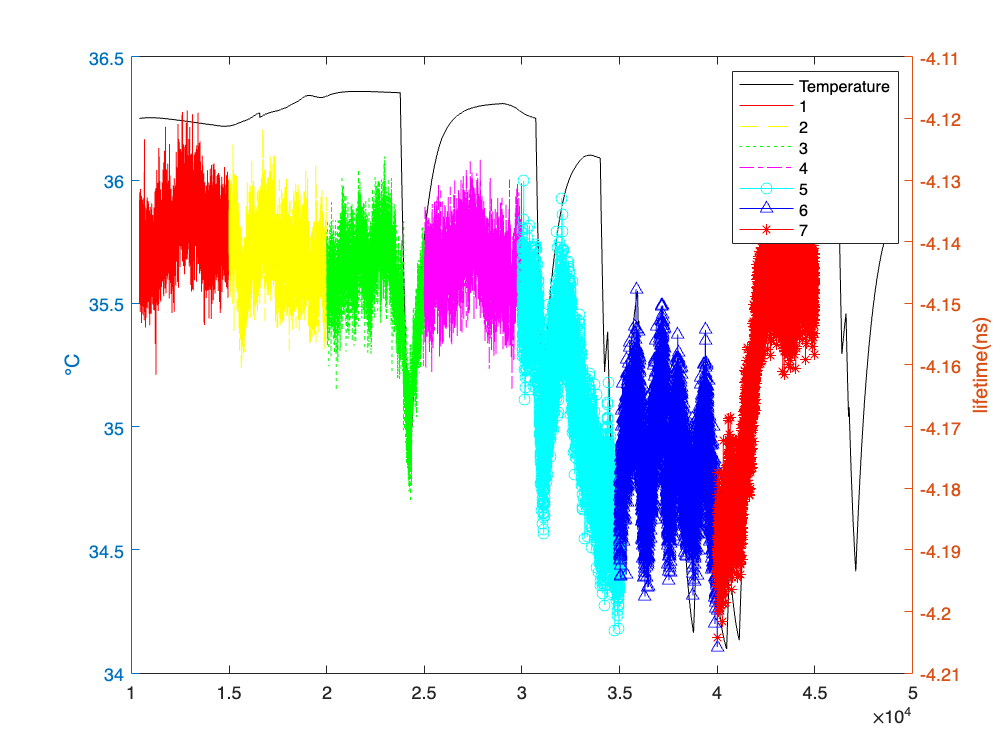

ylabel('lifetime(ns)')
hold off
yyaxis left
plot(time_modified,T_modified,'Color','black')
ylabel('℃')
legend('Temperature','1','2','3','4','5','6','7','8')

% Y = -0.01899*X + 4.833 linear regression from prism
% "Y = -0.01854*X + 4.789"
% Y = -0.01248*X + 4.582
% "Y = -0.01348*X + 4.596"

% k=-00.01899
% k=-0.01854;
% k=-0.01248
k=-0.01348

k = -0.0135

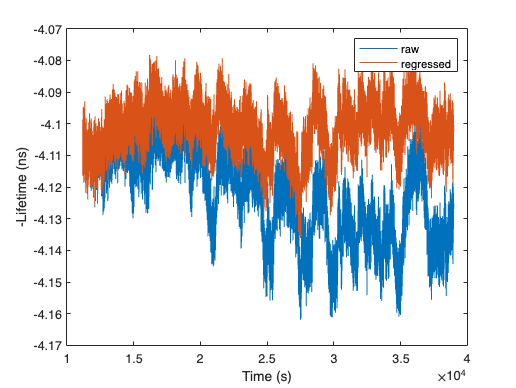



T_diff=T_modified-T_modified(1);
tau_diff=T_diff*k;

tau_regressed=tau_modified-tau_diff';

figure
plot(time_modified,-tau_modified)
hold on
plot(time_modified,-tau_regressed)
ylabel('-Lifetime (ns)')
xlabel('Time (s)')
legend('raw','regressed')

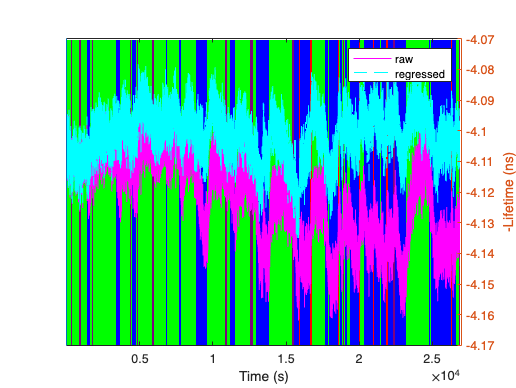

figure
yyaxis left
imagesc(states_modified)
caxis([1 4])
colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
colorbar('off')
set(gca, 'YTick', []);

yyaxis right
plot(-tau_modified,'Color','magenta')
hold on
plot(-tau_regressed,'Color','cyan')
ylabel('-Lifetime (ns)')
xlabel('Time (s)')
legend('raw','regressed')